# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Prob_Stim\RawData_new_new'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = false;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\Prob_Stim\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {5 17};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {6 18};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[14 15 16] [41 42] [51 52] [31 34] [37 38] [22 23] [71] [72] [73] [74] [75] [76] [81:83] [90 91]};   
    Deci.DT.Locks      = [12 30 20];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {110};
    Deci.DT.Block.End = {117};
    Deci.DT.Block.Markers = {111 113 115};

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []   ;
Deci.PP.Ocu = [];
Deci.PP.eog = {'TVEOG','BVEOG','LHEOG','RHEOG'};


## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =false;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.LocksTitle = {'Stim' 'Rsp' 'Fdb'};
Deci.Analysis.DownSample = 500;

Deci.Analysis.Conditions    = {[22] [23]};
Deci.Analysis.CondTitle     = {'Correct' 'Incorrect'};                                               

#### Time-Frequency Analysis

Deci.Analysis.Freq.do = true;
Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(1),log(80),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 
Deci.Analysis.Channels = {'FCz', 'CP3'};

Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

%Cross-Frequency Coupling

Deci.Analysis.CFC.do = true;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1]; %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'beta';
Deci.Analysis.CFC.freqlow = 'theta';
Deci.Analysis.CFC.keeptrials = 'no'

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 5
        Proceed: 0
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]
            Art: [1×1 struct]
       Analysis: [1×1 struct]


Deci.Analysis.CFC.timebin = 1;
Deci.Analysis.CFC.method = 'mi';  % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];


Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 20]};

Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [true];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Analysis.Conditions = {[34] [31]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;
    Deci.Plot.Scale = 'linear';

#### Math

%Deci.Plot.Math.Form = {'[x4+x2]/2','[x7+x5]/2','[x2+x5]/2','[x4+x7]/2' '[x17-x18]' '[x19-x20]'...
 %                      '[x2-x4]','[x5-x7]','[x4-x7]','[x2-x5]' '[[x2+x3+x4+x13+x14+x15]/6]' '[[x5+x6+x7+x10+x11+x12]/6]' '[x27-x28]' ...
  %                     '[x4+x2+x12+x10]/2','[x7+x5+x15+x13]/2','[x2+x5+x10+x13]/2','[x4+x7+x12+x15]/2' '[x2+x3+x4]/3' '[x13+x14+x15]/3' '[x5+x6+x7]/3' '[x10+x11+x12]/3'  ...
   %                     '[x2+x10]' '[x3+x11]/2' '[x4+x12]/2' '[x5+x13]/2' '[x6+x14]/2' '[x7+x15]/2'};   
                    
                        
                      Deci.Plot.Math.Form = {'['};    
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[2 4 5 7] [17:18] [19:20] [21:22] [23:24] [25] [26] [27:28] [29] [30 31] [32 33] [34:37] [38:43] [2:7 10:15]};
Deci.Plot.Title = {'All Opt 10 trials' 'Opt Prediction Error' 'Opt Valence Signals' 'Valence-independent Prediction Error' 'PE-independent Valence Signals' ...
                    'Valence-Dependent Prediction Error' 'PE-dependent Valence Signal' 'Expectation Signals' 'Expectation Subtraction' 'Prediction Error' 'Valence Signals' 'Expectations Signals' 'All Fdb Trials' 'All Resp Trials'};
Deci.Plot.Subtitle = {{'+R' '+P' '-R' '-P'} {'+' '-'} {'R' 'P'} {'+R - +P' '-R - -P'} {'+P - -P' '+R - -R'} {'+ - -'} {'R - P'} {'[BTEOpt+WTEWor]' '[WTEOpt+BTEWor]'} {'[BTEOpt+WTEWor]-[WTEOpt+BTEWor]'} ...
                    {'+' '-'} {'R' 'P'} {'Opt+' 'Wte-' 'Wte+' 'Opt-'} {'+R' '+0' '+P' '-R' '-0' '-P'} {'O_+R' 'O_+0' 'O_+P' 'O_-R' 'O_-0' 'O_-P' 'W_+R' 'W_+0' 'W_+P' 'W_-R' 'W_-0' 'W_-P'}};
Deci.Plot.Figures = [true false false false false false false false false  false  false false  false  false];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8]

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 5
        Proceed: 0
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]
            Art: [1×1 struct]
       Analysis: [1×1 struct]
           Plot: [1×1 struct]


Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = {'FCz'};
Deci.Plot.Freq.Type = 'ITPC';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Analysis.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='none';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =1;

Deci.Plot.Freq.Wires.avg =  'freq';
Deci.Plot.Freq.Wires.errorbars = true ;

Deci.Plot.CFC.errorbars = true ;
Deci.Plot.CFC.Topo = 0;
Deci.Plot.CFC.Square = 0;
Deci.Plot.CFC.Hist = 0;
Deci.Plot.CFC.Wire = 1;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest


**ERP**

Deci.Plot.ERP.Toi = [];
Deci.Plot.ERP.Channel = {'FCz'};

Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time

Deci.Plot.ERP.Topo =0;
Deci.Plot.ERP.Wires =1;
Deci.Plot.ERP.errorbars =  true;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [true];
Deci.Plot.Behv.Acc.Total = {{[1:2] [1:2]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1] [2]}};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {{'Cor Percent' 'Inc Percent'}};

Deci.Plot.Behv.Acc.Block = [111:2:115];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = false;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;

Deci.Plot.Behv.RT.Figure = [true];
Deci.Plot.Behv.RT.Draw = {{[1] [2]}};
Deci.Plot.Behv.RT.Title = {{'All Trials RT' 'All Trials Percent'}};
Deci.Plot.Behv.RT.Subtitle = {{'Cor' 'Inc'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [111:2:115];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = false;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = true;
Deci.Run.Freq =false;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

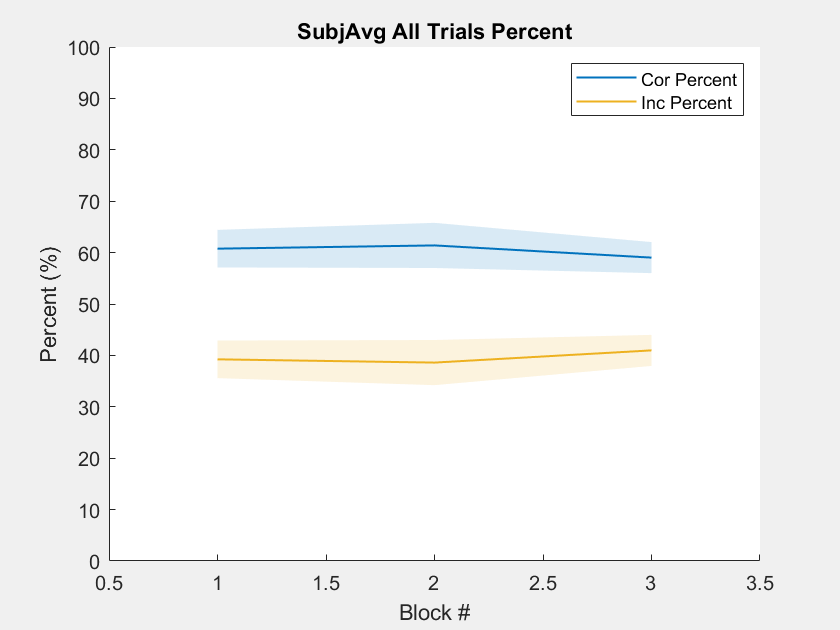

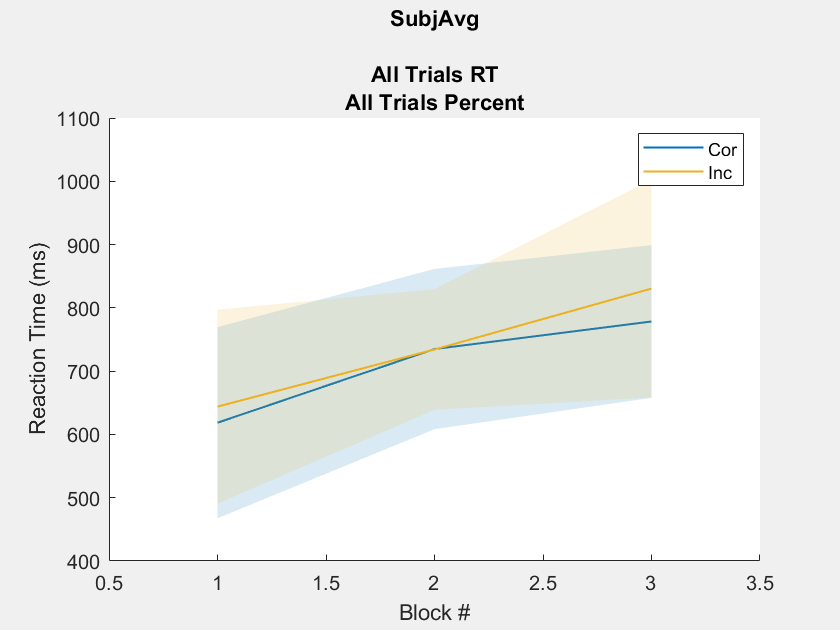


Deci_Backend(Deci);